## Boxplot of latency (comparison b/w manual and automated)

V1 = VariableStimuli (:,1)

Unrecognized function or variable 'VariableStimuli'.

V2 = VariableStimuli (:,2)
boxplot ([V1(:) V2(:)]);
hold on
plot (1,V1, 'o', 2, V2, 'o', 'MarkerFaceColor','k')
xticklabels ({'Time to first spike (Manual)', 'Time to first spike (Automated)'})
ylabel ('Latency (ms)')
title ('Latency of response to variable stimuli')
legend ('n = 11')
saveas(gcf, 'Latency-VariableStimuli', 'pdf');
ylim ([0 800])

S1 = StableStimuli (:,1)
S2 = StableStimuli (:,2)
boxplot ([S1(:) S2(:)]);
hold on
plot (1,S1, 'o', 2, S2, 'o', 'MarkerFaceColor','k')
xticklabels ({'Time to first spike (Manual)', 'Time to first spike (Automated)'})
ylabel ('Latency (ms)')
title ('Latency of response to stable stimuli')
legend ('n = 35')
saveas(gcf, 'Latency-StableStimuli', 'pdf')
ylim ([0 800])

## Mean latency with satndard deviation for all muscles

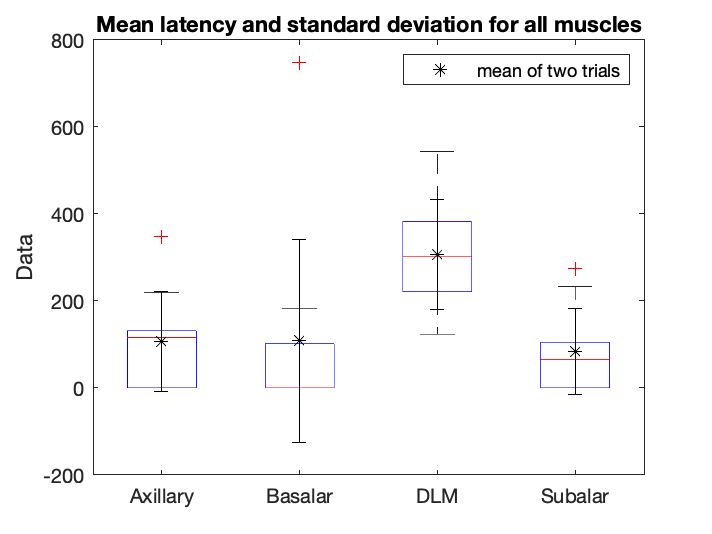

data = latency(:,:);
groupNames = {'Axillary','Basalar','DLM','Subalar'};

% box plot with mean and standard deviation
figure;
boxplot(data,'Labels',groupNames);
hold on;
meanData = mean(data);
stdData = std(data);
numGroups = size(data,2);
for i=1:numGroups
    x = repmat(i,1,size(data,1));
    plot(x,meanData(:,i),'k*');
    errorbar(i,meanData(i),stdData(i),'k');
end
ylabel('Data'); ylim([-200 800]);
legend ('mean of two trials')
title('Mean latency and standard deviation for all muscles');

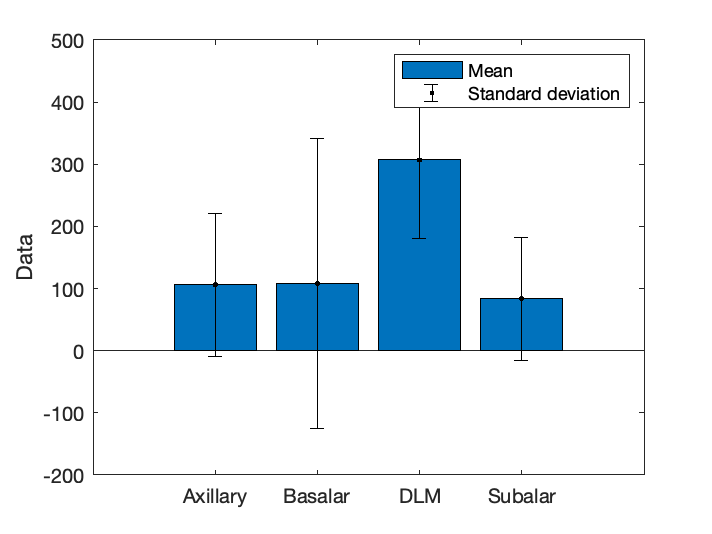

data = latency(:,:);
groupNames = {'Axillary','Basalar','DLM','Subalar'};

% Compute mean and standard deviation
meanData = mean(data);
stdData = std(data);

% Plot bar chart with error bars
figure;
bar(meanData);
hold on;
errorbar(meanData,stdData,'.','color','k');
set(gca,'XTick',1:numel(groupNames),'XTickLabel',groupNames);
ylabel('Data');
legend({'Mean','Standard deviation'});